# **Control usando estimación de estados **

Agregue un controlador en espacio de estados al sistema del ejercicio 2, como se indica en la figura.

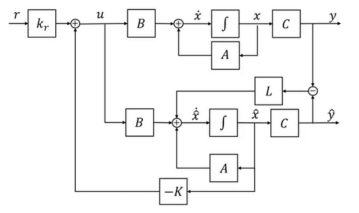

**1)** Determine el polinomio deseado para un overshoot del 2% y un settling time de 1 s para la variable de salida del sistema.

Se elegirá como matriz de salida del sistema a C = [0 1 0], es decir para estimar el estado interno del sistema se elegirá sensar la velocidad de giro de la rueda.

close all; clear; clc;
% Parámetros númericos.
Jc = 6250;
Jf = 0.625;
ds = 1000;
cs = 75000;
i = 57;
% Matrices númericas.
A = [-ds/(Jf*i^2)  ds/(Jf*i) -cs/(Jf*i);
     ds/(Jc*i)    -ds/Jc      cs/Jc;
     1/i          -1          0];
Bu = [1/Jf;0;0];
Bd = [0;-1/Jc;0];
B = Bu;
C = [0 1 0];
D = [0];
I = eye(3);

A partir de considerar polos complejos conjugados, partiremos de una estimación inicial de parámetros hasta encontrar los parámetros deseados. El polo restante lo colocaremos lejos para que no interfiera en la respuesta.

Entonces, según una serie de expresiones, podemos decir que:


$$\zeta =\frac{\ln \left(M_p \right)}{\sqrt{\pi^2 +{\left(\ln \left(M_p \right)\right)}^2 }}$$



$$\omega_n \approx \frac{4}{\zeta T_s }$$


Para este caso:


$$\begin{array}{l}
\zeta =0\ldotp 779\\
\omega_n =5,128\;\textrm{rad}/s
\end{array}$$


syms s % Variable compleja.
zeta = 0.779; % Amortiguamiento.
wn0 = 5.128; % Frecuencia natural incial.
disp('El polinomio deseado del sistema es:')

El polinomio deseado del sistema es:


p_deseado = expand((s+10*wn0)*(s^2 + 2*zeta*wn0*s + wn0^2)) % Polinomio deseado.

$$p\_deseado = s^{3}+\frac{1668285974005399593\,s^{2}}{28147497671065600}+\frac{245442828292993343\,s}{562949953421312}+\frac{4744537181417633347}{3518437208883200}$$

coef_deseado = coeffs(p_deseado, s); % Coeficientes simbólicos del polinomio anterior.
coef_deseado_double = double(coef_deseado); % Coeficientes en formato double.
Ha = tf([1],[coef_deseado_double(1,4) coef_deseado_double(1,3) coef_deseado_double(1,2) coef_deseado_double(1,1)]); % Función de transferencia.
disp('Los polos del polinomio deseado son:')

Los polos del polinomio deseado son:


disp(pole(Ha))

 -51.2800 + 0.0000i
  -3.9947 + 3.2154i
  -3.9947 - 3.2154i



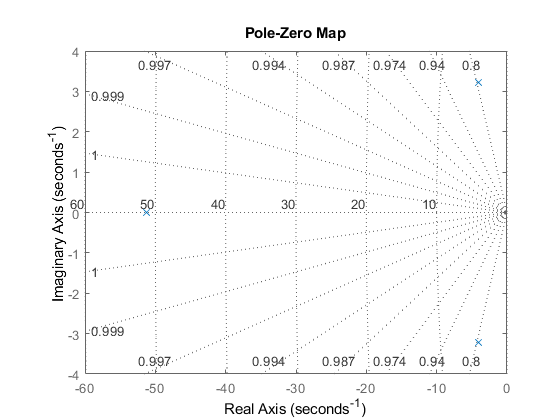

pzmap(Ha) % Graficamos los polos y ceros en el plano de Laplace.
grid on

ha = stepplot(Ha) % Respuesta al escalón unitario.


ha =

	resppack.timeplot



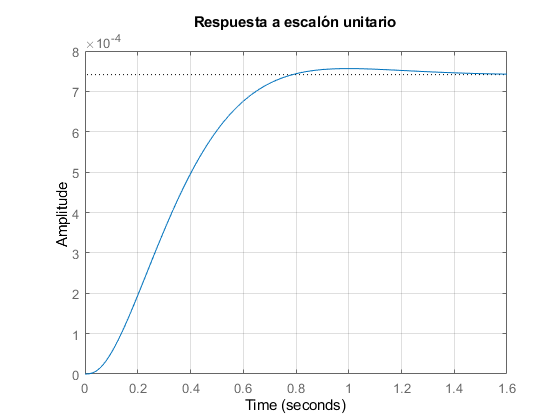

setoptions(ha,'Grid','on');
title('Respuesta a escalón unitario')

sa = stepinfo(Ha) % Buscamos las especificaciones de diseño del sistema.

sa = struct with fields:
        RiseTime: 0.4683
    SettlingTime: 1.0146
     SettlingMin: 6.6847e-04
     SettlingMax: 7.5645e-04
       Overshoot: 2.0063
      Undershoot: 0
            Peak: 7.5645e-04
        PeakTime: 1.0030



% Coeficientes del polinomio deseado.
p3 = coef_deseado_double(1,1);
p2 = coef_deseado_double(1,2);
p1 = coef_deseado_double(1,3);

**2)** Cierre el bucle de control a través del observador. Encuentre el valor de la matriz K.

A partir de la formula de Ackerman encontramos el valor de la matriz K y de la constante kr.

disp('Polinomio característico:')

Polinomio característico:


p_caracteristico = det(s*I-A)

$$p\_caracteristico = s^{3}+\frac{52996\,s^{2}}{81225}+\frac{52996\,s}{1083}$$

coef_caracteristico = coeffs(p_caracteristico,s); % Obtenemos los coeficientes simbólicos del polinomio característico.
coef_caracteristico_double = double(coef_caracteristico); % Coeficientes formato double.
% Coeficientes del polinomio característico.
a3 = 0;
a2 = coef_caracteristico_double(1,1);
a1 = coef_caracteristico_double(1,2);

% Formula de Ackermann.
Wr = [B A*B A^2*B] % Matriz de alcanzabilidad.

Wr =     1.6000   -0.7879  -58.5810
         0    0.0045    0.3339
         0    0.0281   -0.0183


Wr_tilde = inv([1 a1 a2;
                0 1  a1;
                0 0  1])

Wr_tilde =     1.0000   -0.6525  -48.5087
         0    1.0000   -0.6525
         0         0    1.0000


K = [p1-a1 p2-a2 p3-a3]*Wr_tilde*inv(Wr)

K = 	1.0e+04 *

    0.0037    0.1915    1.3148


% Corroboración.
Kprima = acker(A,B,pole(Ha))

Kprima = 	1.0e+04 *

    0.0037    0.1915    1.3148


% Establecemos los polos del observador como 5 veces más rapidos que el
% polo más rápido del sistema a lazo cerrado.
disp('Situamos los polos del observador en lazo cerrado en:')

Situamos los polos del observador en lazo cerrado en:


p = -(10*wn0)*5

p = -256.4000

disp('Polinomio deseado del observador a lazo cerrado:')

Polinomio deseado del observador a lazo cerrado:


p_deseado = expand((s + -1*p)^3) % Polinomio deseado.

$$p\_deseado = s^{3}+\frac{3846\,s^{2}}{5}+\frac{4930572\,s}{25}+\frac{2106997768}{125}$$

coef_obs_deseado = coeffs(p_deseado, s); % Coeficientes del polinomio deseado.
coef_obs_deseado_double = double(coef_obs_deseado); % Coeficientes en formato double.

syms l1 l2 l3
L = [l1 l2 l3]'; % Matriz de ganancia del obsv. a lazo cerrado.
p_observador = simplify(det(s*I - A + L*C))

$$p\_observador = \frac{52996\,s}{1083}+\frac{4\,\bar{l_{1}}}{19}+\frac{40000\,\bar{l_{2}}}{1083}+s^{2}\,\bar{l_{2}}+\frac{4\,s\,\bar{l_{1}}}{1425}+\frac{1600\,s\,\bar{l_{2}}}{3249}+12\,s\,\bar{l_{3}}+\frac{52996\,s^{2}}{81225}+s^{3}$$

coef_obs = coeffs(p_observador, s) % Coeficientes del polinomio del observador.

$$coef\_obs = \left(\begin{array}{cccc} \frac{4\,\bar{l_{1}}}{19}+\frac{40000\,\bar{l_{2}}}{1083} & \frac{4\,\bar{l_{1}}}{1425}+\frac{1600\,\bar{l_{2}}}{3249}+12\,\bar{l_{3}}+\frac{52996}{1083} & \bar{l_{2}}+\frac{52996}{81225} & 1 \end{array}\right)$$


% Igualamos los coeficientes.
eqns = [coef_obs == coef_obs_deseado_double];

% Resolvemos las ecuaciones.
sol = solve(eqns, [l1, l2, l3]);

% Mostramos los coeficientes resultantes.
disp("Los coeficientes del polinomio simbólico son:");

Los coeficientes del polinomio simbólico son:


l1_double = double(sol.l1);
l2_double = double(sol.l2);
l3_double = double(sol.l3);
disp('l1:')

l1:


disp(l1_double);

   7.9931e+07



disp('l2:')

l2:


disp(l2_double);

  768.5475



disp('l3:')

l3:


disp(l3_double);

  -2.2977e+03




% Corroboramos:
polos_deseados = eig(A - [l1_double l2_double l3_double]'*C)

polos_deseados = 	1.0e+02 *

  -2.5640 + 0.0000i
  -2.5640 + 0.0000i
  -2.5640 - 0.0000i


% Corroboración.
Lprima = acker(A',C',[p p p])'

Lprima = 	1.0e+07 *

    7.9931
    0.0001
   -0.0002


**3)** Determine el valor de kr.

kr = -1/(C*inv(A-B*K)*B)

kr = 4.0033e+03

**4)** Grafique las variables de interés del sistema.

A continuación se observa la evolución de las variables de estado del sistema, tanto en el mismo sistema como en el observador. Se observa la convergencia de las variables estimadas a las reales, con lo cual el modelado fue un éxito.